%%  Разбор данных
% запись путей
addpath(genpath('E:\ExchangeRateStability\MotorcycleBooks\Models'))


% загрузка - дома
% загрузить данные из катадога
path_data = 'E:\MotoDan\mU'

% загрузка - на работе
% загрузить  данные из катадога
path_data = 'E:\ExchangeRateStability\Log'


%name_file = "20210930_1_50kg_200kmh"

name_file = "T3_2021-10-08_10-33"

name_file = "T3_2021-10-08_10-33"

name_file = "T5_2021-10-08_10-44"

name_file = "T5_2021-10-08_10-44"


load('-mat', path_data+"\"+name_file+'.mat');

YAcc=DanConvert.XYZg.YawAcc';
YAccF = FiltrCheb(YAcc);
step=10

step = 10

Ms=zeros(step,1);

YAccFabs = abs(YAccF);
YAccF1 = zeros(length(YAccFabs),1);       % cumtrapz(abs(YAccF), 0.01);
for i =1: length(YAccFabs)
  Ms=[Ms(2:step); YAccFabs(i)];
  YAccF1(i) = sum(Ms);
end



% разность между колесами
disp("погрешность смещения")
z=DanConvert.vBelt.F - DanConvert.vBelt.R;
Vxerror=zeros(length(DanConvert.vBelt.F),1);
for i = 1:length(DanConvert.vBelt.F)
    Vxerror(i)= z(i)/max(DanConvert.vBelt.F(i), DanConvert.vBelt.R(i));
end
Vxerror(1:10)=0;

% тест формулы 1-(V/w*R)
r0 = 25.4*17/1000;
%V = DanConvert.speed;
V = DanConvert.vBelt.F;
kp=3;
%w0=2*pi*f
vr=r0*DanConvert.Engine.Rotv/kp;
s0 = 1-(V./(vr))
figure
plot(s0)
title("Проскальзование")

%  расчет mu

fx = DanConvert.Frc.X;
nx = DanConvert.Frc.Z;
muu = fx./nx
figure
plot(muu)
title("mU")


% филтер Калман

[x(:,3), x(:,2),  x(:,1)] = MasKalman(DanConvert.XYZg.RollVel');
[y(:,3), y(:,2),  y(:,1)] = MasKalman(DanConvert.XYZg.PitchVel');
[z(:,3), z(:,2),  z(:,1)] = MasKalman(DanConvert.XYZg.YawVel');
dt=0.01
for i = 1:length(x(:,1))
    state = [x(i,1); x(i,2); x(i,3); y(i,1); y(i,2); y(i,3); z(i,1); z(i,2); z(i,3)];
    m(i,:)= constacc(state, dt);
end






mx(:,1)=y(:,1);
mx(:,2)=m(:,4);
plot(mx,'DisplayName','mx')

% подключение FFT
step = 10;
nfft = 128*2;
limit = 20;
count = length(DanConvert.Time);
Npoint = fix(count/step);
t=linspace(1,limit, limit);
%myFFT = MyFFT(DanConvert.Time, DanConvert.XYZg.YawAcc, step, nfft, limit); 
myFFT = MyFFT(DanConvert.Time, YAccF, step, nfft, limit); 
k=1;
i=1

i = 1

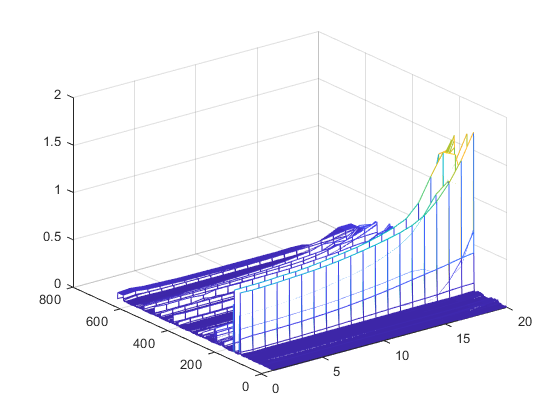

M=zeros(Npoint,limit);
V=zeros(Npoint,2);
Verror=zeros(Npoint,1);
while i<Npoint
%for i = 1:Npoint
    %timex=string(k*0.01)+" Sec."
    Y = myFFT.OneStep(k);
    M(i,:)=Y;
%    k0=k; if k0>count k0=count end
    %V(i, 1)=Dan1.vBelt.F(k0);
    %V(i, 2)=Dan1.vBelt.R(k0);
    %Verror(i)=(Dan1.vBelt.F(k0) -Dan1.vBelt.R(k0))/max(Dan1.vBelt.F(k0), Dan1.vBelt.R(k0));
%    figure;%    plot(t,Y)%    grid on;
    k=k+step;
    i=i+1;
end    
figure;
mesh(M)

function [z, vx, w] = MasKalman(w)
    function p=f0(w0)
        count = length(w0);
        vxx=[0.0; w0];
        vxx=vxx(1: count);
        p=vxx-w0;
    end
    vx=f0(w);
    z=f0(vx);
end

